# Vision Sensor - Estimating Distance from robot base

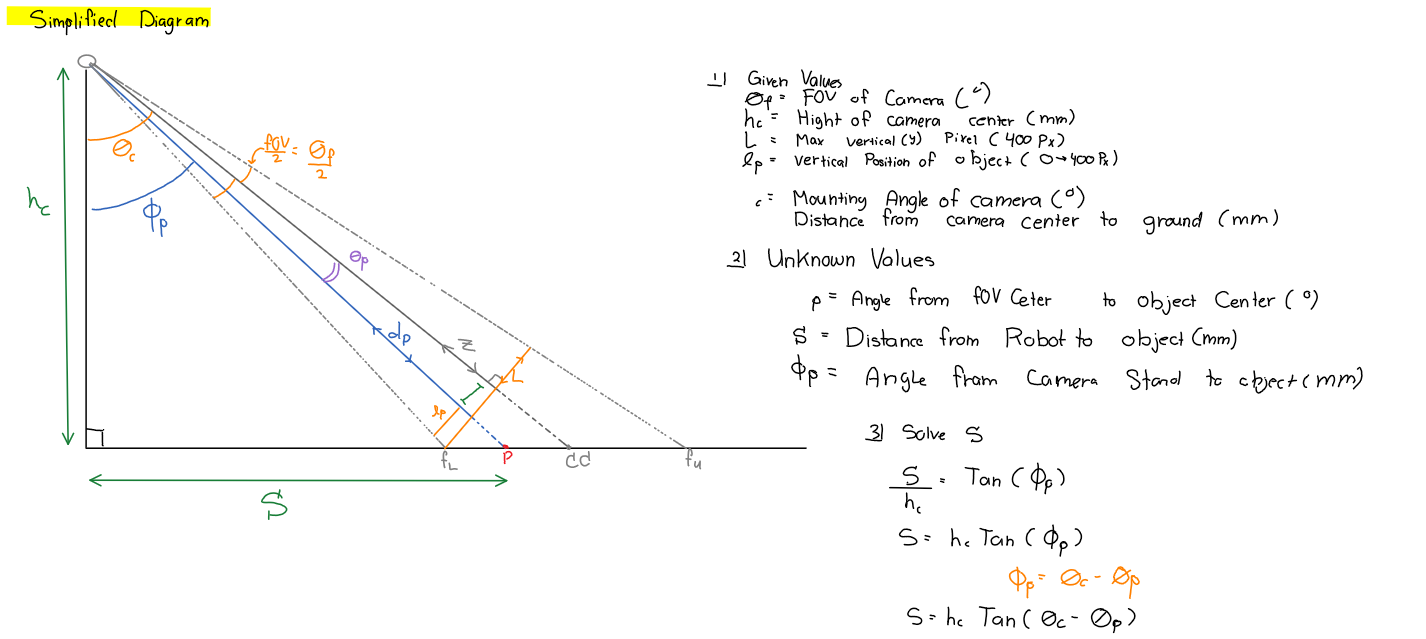

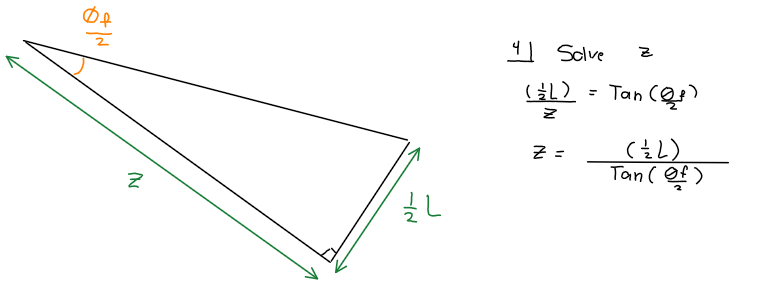

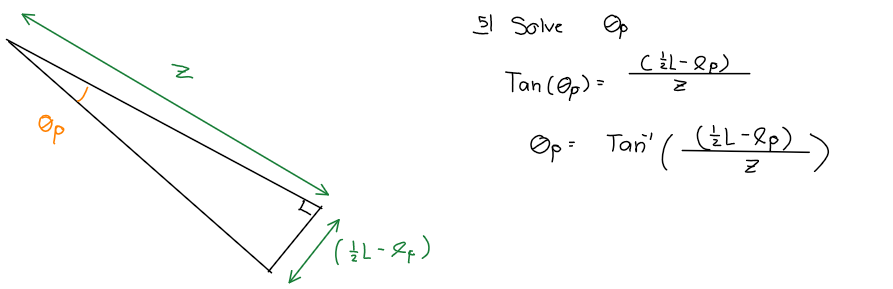

%clear memory, workspace, close figures
clc, clear,close all

% Create symbolic Variabels
syms theta_f h_c L l_p theta_c z theta_p s phi_p

%plug in known

% solve for the distance from camera center to object
z = simplify(0.5*L) / (tand(theta_f /2)) % mm

$$z = \frac{L}{2\,\tan\left(\frac{\pi \,\theta_{f}}{360}\right)}$$


% Solve for the theta_p of the object
theta_p = simplify(atand( (0.5*L - l_p) / z  )) % degree

$$theta\_p = \frac{180\,\mathrm{atan}\left(\frac{\tan\left(\frac{\pi \,\theta_{f}}{360}\right)\,\left(L-2\,l_{p}\right)}{L}\right)}{\pi }$$


%create equation to solve for Distance to robot base
s = h_c*tand(theta_c - theta_p) % mm

$$s = h_{c}\,\tan\left(\frac{\pi \,\left(\theta_{c}-\frac{180\,\mathrm{atan}\left(\frac{\tan\left(\frac{\pi \,\theta_{f}}{360}\right)\,\left(L-2\,l_{p}\right)}{L}\right)}{\pi }\right)}{180}\right)$$

simplify(s)

$$ans = -h_{c}\,\tan\left(\mathrm{atan}\left(\frac{\tan\left(\frac{\pi \,\theta_{f}}{360}\right)\,\left(L-2\,l_{p}\right)}{L}\right)-\frac{\pi \,\theta_{c}}{180}\right)$$